# Exercise 1

f = @(x) exp(-x.^2);
a = 1;
b = 1.5;

midpoint = (a + b)/2;
rect_area = (b - a) * f(midpoint);
fprintf('a) Rectangle formula approximation: %.6f\n', rect_area);

a) Rectangle formula approximation: 0.104806


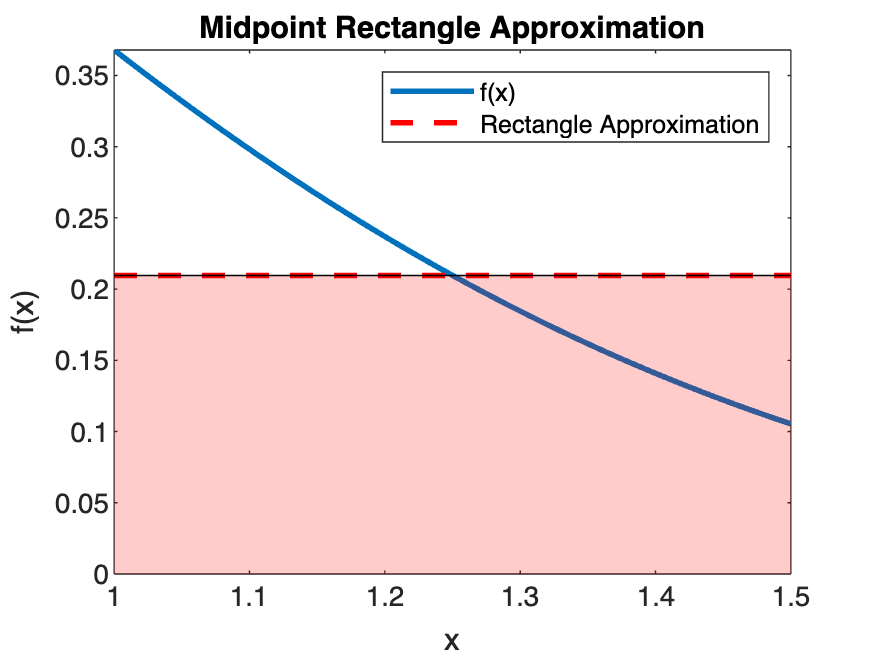

figure;
fplot(f, [a b], 'LineWidth', 2); hold on;
plot([a b], [f(midpoint) f(midpoint)], 'r--', 'LineWidth', 2);
area([a b], [f(midpoint) f(midpoint)], 'FaceAlpha', 0.2, 'FaceColor', 'r');
xlabel('x');
ylabel('f(x)');
legend('f(x)', 'Rectangle Approximation');
title('Midpoint Rectangle Approximation');

n1 = 150;
n2 = 500;

x1 = linspace(a, b, n1+1);
midpoints1 = (x1(1:end-1) + x1(2:end))/2;
h1 = (b - a) / n1;
rect_sum1 = h1 * sum(f(midpoints1));
fprintf('c) Approximation with n=150: %.6f\n', rect_sum1);

c) Approximation with n=150: 0.109364


x2 = linspace(a, b, n2+1);
midpoints2 = (x2(1:end-1) + x2(2:end))/2;
h2 = (b - a) / n2;
rect_sum2 = h2 * sum(f(midpoints2));
fprintf('c) Approximation with n=500: %.6f\n', rect_sum2);

c) Approximation with n=500: 0.109364


## Exercise 2

f = @(x) 2 ./ (1 + x.^2); 
a = 0; b = 1;             
epsilon = 1e-4;           

maxLevel = 10;
R = zeros(maxLevel, maxLevel);
h = b - a;
R(1,1) = h * (f(a) + f(b)) / 2;

for k = 2:maxLevel
    h = h / 2;
    sum_f = 0;
    for i = 1:2^(k-2)
        sum_f = sum_f + f(a + (2*i - 1)*h);
    end
    R(k,1) = 0.5 * R(k-1,1) + h * sum_f;
    for j = 2:k
        R(k,j) = R(k,j-1) + (R(k,j-1) - R(k-1,j-1)) / (4^(j-1) - 1);
    end
    if abs(R(k,k) - R(k-1,k-1)) < epsilon
        break;
    end
end

fprintf('Romberg (Trapezoid) result = %.5f\n', R(k,k));

Romberg (Trapezoid) result = 1.57080


R_diag = diag(R(1:k, 1:k)); 
aitken_vals = zeros(k-2, 1);

for i = 1:k-2
    delta1 = R_diag(i+1) - R_diag(i);
    delta2 = R_diag(i+2) - R_diag(i+1);
    aitken_vals(i) = R_diag(i) - (delta1^2) / (delta2 - delta1);
end

fprintf('Romberg with Aitken result = %.5f\n', aitken_vals(end));

Romberg with Aitken result = 1.57080


## Exercise 3

f3 = @(x) (100./x.^2) .* sin(10./x);
a3 = 1;
b3 = 3;

S = (b3 - a3)/6 * (f3(a3) + 4*f3((a3+b3)/2) + f3(b3));
c = (a3+b3)/2;
left = (c - a3)/6 * (f3(a3) + 4*f3((a3+c)/2) + f3(c));
right = (b3 - c)/6 * (f3(c) + 4*f3((c+b3)/2) + f3(b3));
if abs(left + right - S) <= 15*eps
    adaptive_result = left + right + (left + right - S)/15;
else
    c1 = (a3+c)/2;
    c2 = (c+b3)/2;
    left1 = (c - a3)/6 * (f3(a3) + 4*f3(c1) + f3(c));
    right1 = (b3 - c)/6 * (f3(c) + 4*f3(c2) + f3(b3));
    adaptive_result = left1 + right1;
end
fprintf('Adaptive Simpson''s result: %.8f\n', adaptive_result);

Adaptive Simpson's result: -14.39755533


n50 = 50;
h50 = (b3 - a3)/n50;
x50 = linspace(a3, b3, n50+1);
y50 = f3(x50);
simpson50 = (h50/3)*(y50(1) + 2*sum(y50(3:2:end-2)) + 4*sum(y50(2:2:end)) + y50(end));
fprintf('Repeated Simpson''s result with n=50: %.8f\n', simpson50);

Repeated Simpson's result with n=50: -1.42436853


n100 = 100;
h100 = (b3 - a3)/n100;
x100 = linspace(a3, b3, n100+1);
y100 = f3(x100);
simpson100 = (h100/3)*(y100(1) + 2*sum(y100(3:2:end-2)) + 4*sum(y100(2:2:end)) + y100(end));
fprintf('Repeated Simpson''s result with n=100: %.8f\n', simpson100);

Repeated Simpson's result with n=100: -1.42592037


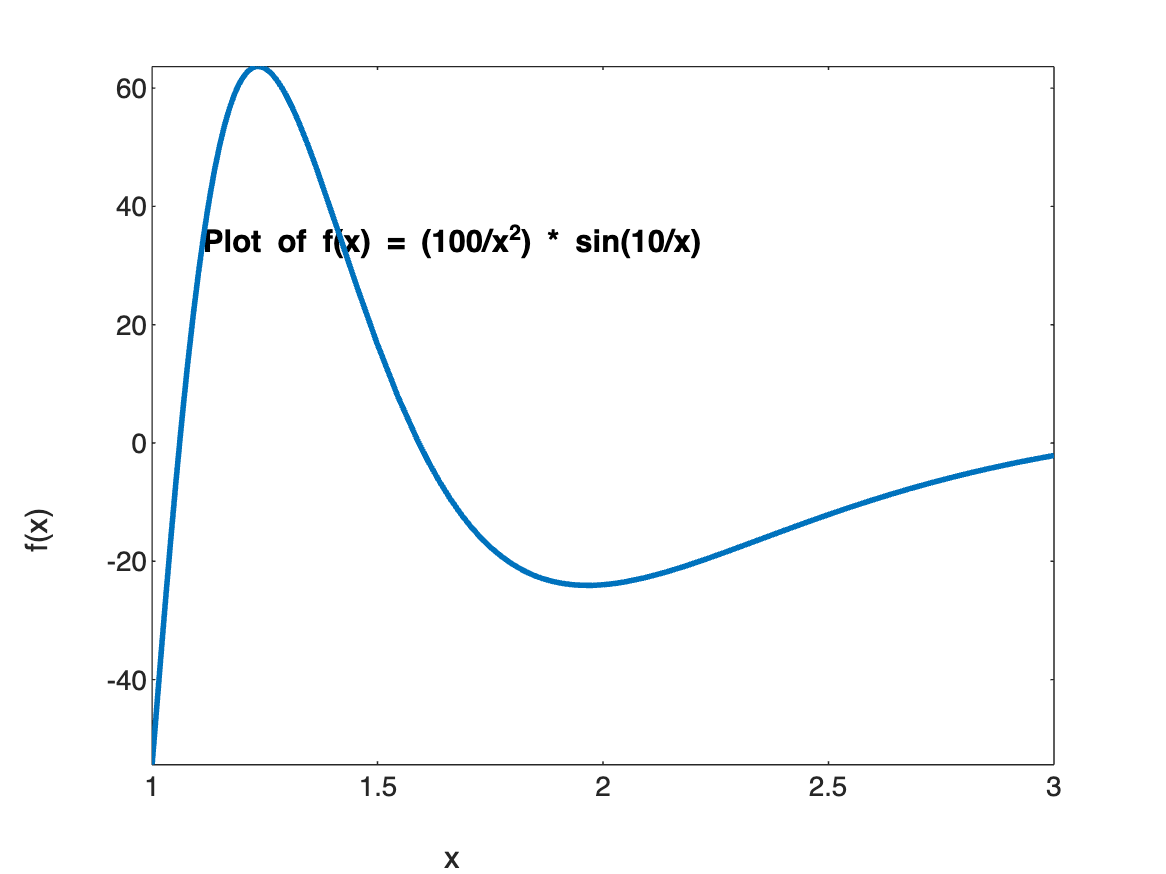

figure;
fplot(f3, [1 3], 'LineWidth', 2);
xlabel('x');
ylabel('f(x)');
title('Plot of f(x) = (100/x^2) * sin(10/x)');